## RISOLUZIONE PIASTRA  CIRCOLARE SU LETTO DI MOLLE CON CARICO DISTRIBUITO E MOMENTO FLETTENTE AL BORDO 

%% Clear workspace and close any open windows
clear all
close all

## SIMBOLICO

syms c1 c2 c3 c4 c5 c6 r real
digits(5) %per arrotondare

## NUMERICO

R=1000; % raggio serbatoio [mm]
E=210000; % Young's modulus steel [N/mm^2] se.. 2.1E11[N/m^2] 
nu=0.3; % coefficiente di Poisson acciaio
t=R/50; %spessore serbatoio
h=5*R; %altezza serbatoio
gamma=0.000001; % acqua N/mm3
D=(E*t^3)/(12*(1-nu^2)); % rigidezza
k=0.0210 %- 0.108 (N/mm3) % sabbia

k =           0.02


mo=650 % bisognerebbe conoscere il vero valore di mo che viene applicato

mo =         650.00


## METODO DI RAYLEIGH-RITZ

p2=gamma*h %carico idrostatico sulla piastra

p2 =           0.01


wk(r)=c1*r^5+c2*r^4+c3*r^3+c4*r^2+c5*r+c6

$$wk(r) = c_{1}\,r^{5}+c_{2}\,r^{4}+c_{3}\,r^{3}+c_{4}\,r^{2}+c_{5}\,r+c_{6}$$

% i parametri A,B,C,D,E sono parametri cinematiche ( devo cercare quello stazionario)
% mentre le s^n sono le funzioni fi forma prese per approssimare meglio lo spostamento

## derivate di wk(r)

wk_r(r)=diff(wk,r) % derivata prima

$$wk\_r(r) = 5\,c_{1}\,r^{4}+4\,c_{2}\,r^{3}+3\,c_{3}\,r^{2}+2\,c_{4}\,r+c_{5}$$

wk_rr(r)=diff(wk_r,r) % derivata seconda

$$wk\_rr(r) = 20\,c_{1}\,r^{3}+12\,c_{2}\,r^{2}+6\,c_{3}\,r+2\,c_{4}$$

## Applico le Condizioni al contorno:

cc_1=wk_r(0)==0                          

$$cc\_1 = c_{5}=0$$

% l'unica condizione al contorno che posso scrivere è questa.
% il metodo di ritz prevede che le condizioni al contorno da rispettare 
% siano solo condizioni cinematiche e non delle CDS.
S=solve([cc_1],[c4])

 
S =
 
Empty sym: 0-by-1
 


wk(r)=simplify(subs(wk,[c5],[0]))

$$wk(r) = c_{1}\,r^{5}+c_{2}\,r^{4}+c_{3}\,r^{3}+c_{4}\,r^{2}+c_{6}$$

## derivate di wk(r)

wk_r(r)=diff(wk,r) % derivata prima

$$wk\_r(r) = 5\,c_{1}\,r^{4}+4\,c_{2}\,r^{3}+3\,c_{3}\,r^{2}+2\,c_{4}\,r$$

wk_rr(r)=diff(wk_r,r) % derivata seconda

$$wk\_rr(r) = 20\,c_{1}\,r^{3}+12\,c_{2}\,r^{2}+6\,c_{3}\,r+2\,c_{4}$$

## Ricavo le MdD e le CDS

%MdD=misure di deformazione

%CDS= caratteristiche della sollecitazione

mr(r)=vpa(D*(-wk_rr(r)-nu*wk_r(r)/r))

$$mr(r) = -3.0769\,10^{8}\,c_{4}-9.2308\,10^{8}\,c_{3}\,r-3.0769\,10^{9}\,c_{1}\,r^{3}-1.8462\,10^{9}\,c_{2}\,r^{2}-\frac{1.5385\,10^{8}\,\left(1.5\,c_{1}\,r^{4}+1.2\,c_{2}\,r^{3}+0.9\,c_{3}\,r^{2}+0.6\,c_{4}\,r\right)}{r}$$

m_theta(r)=vpa(D*(-wk_r(r)/r-nu*wk_rr(r)))

$$m\_theta(r) = -9.2308\,10^{7}\,c_{4}-2.7692\,10^{8}\,c_{3}\,r-9.2308\,10^{8}\,c_{1}\,r^{3}-5.5385\,10^{8}\,c_{2}\,r^{2}-\frac{1.5385\,10^{8}\,\left(5.0\,c_{1}\,r^{4}+4.0\,c_{2}\,r^{3}+3.0\,c_{3}\,r^{2}+2.0\,c_{4}\,r\right)}{r}$$

chi_r(r)=-wk_rr

$$chi\_r(r) = -20\,c_{1}\,r^{3}-12\,c_{2}\,r^{2}-6\,c_{3}\,r-2\,c_{4}$$

chi_theta(r)=-wk_r/r

$$chi\_theta(r) = -\frac{5\,c_{1}\,r^{4}+4\,c_{2}\,r^{3}+3\,c_{3}\,r^{2}+2\,c_{4}\,r}{r}$$

% mi serviranno per ricavare l'energia potenziale totale

## ENERGIA POTENZIALE TOTALE


U_el=2*pi*int(1/2*(mr*chi_r+m_theta*chi_theta)*r,r,[0 R]); % energia di deformazione elastica
U_molla=2*pi*int(1/2*(k*wk^2)*r,r,0,R); 
L=int(2*pi*r*p2*wk,r,0,R)+2*pi*R*mo*wk_r(R); % Lavoro fatto dai carichi
V=simplify(U_el+U_molla-L) % Energia potenziale totale

$$V = 3.4799\,10^{34}\,{c_{1}}^{2}+5.3699\,10^{31}\,c_{1}\,c_{2}+3.9294\,10^{28}\,c_{1}\,c_{3}+2.7227\,10^{25}\,c_{1}\,c_{4}+1.885\,10^{19}\,c_{1}\,c_{6}-2.4908\,10^{19}\,c_{1}+2.1806\,10^{28}\,{c_{2}}^{2}+3.438\,10^{25}\,c_{2}\,c_{3}+2.6546\,10^{22}\,c_{2}\,c_{4}+2.1991\,10^{16}\,c_{2}\,c_{6}-2.1572\,10^{16}\,c_{2}+1.4989\,10^{22}\,{c_{3}}^{2}+2.6389\,10^{19}\,c_{3}\,c_{4}+2.6389\,10^{13}\,c_{3}\,c_{6}-1.8535\,10^{13}\,c_{3}+1.3509\,10^{16}\,{c_{4}}^{2}+3.2987\,10^{10}\,c_{4}\,c_{6}-1.6022\,10^{10}\,c_{4}+32987.0\,{c_{6}}^{2}-15708.0\,c_{6}$$

## MINIMO DELL' ENERGIA POTENZIALE TOTALE

V_c1=diff(V,c1)==0;
V_c2=diff(V,c2)==0;
V_c3=diff(V,c3)==0;
V_c4=diff(V,c4)==0;
V_c6=diff(V,c6)==0;

S=solve([V_c1 V_c2 V_c3 V_c4 V_c6],[c1 c2 c3 c4 c6]);    
c_1=simplify(S.c1(1))

$$c\_1 = -4.2375\,10^{-16}$$

c_2=simplify(S.c2(1))

$$c\_2 = 1.1684\,10^{-12}$$

c_3=simplify(S.c3(1))

$$c\_3 = -3.8295\,10^{-10}$$

c_4=simplify(S.c4(1))

$$c\_4 = 2.4654\,10^{-7}$$

c_6=simplify(S.c6(1))

$$c\_6 = -0.00039487$$

## spostamento


wk2(r)=vpa(simplify(subs(wk,[c1 c2 c3 c4 c6],[c_1 c_2 c_3 c_4 c_6])))

$$wk2(r) = -4.2375\,10^{-16}\,r^{5}+1.1684\,10^{-12}\,r^{4}-3.8295\,10^{-10}\,r^{3}+2.4654\,10^{-7}\,r^{2}-0.00039487$$

wk2_r(r)=diff(wk2,r) % derivata prima

$$wk2\_r(r) = -2.1187\,10^{-15}\,r^{4}+4.6737\,10^{-12}\,r^{3}-1.1489\,10^{-9}\,r^{2}+4.9308\,10^{-7}\,r$$

wk2_rr(r)=diff(wk2_r,r) % derivata seconda

$$wk2\_rr(r) = -8.4749\,10^{-15}\,r^{3}+1.4021\,10^{-11}\,r^{2}-2.2977\,10^{-9}\,r+4.9308\,10^{-7}$$

## Plot Soluzione

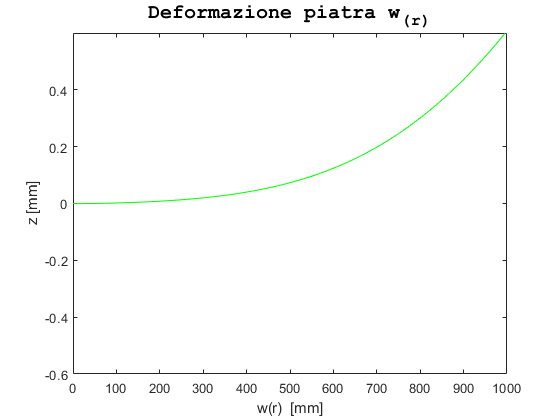

%% Soluzione
a2=0:R/(100-1):R;
figure(5)
plot(a2,double(wk2(a2)),'g')
title(['\fontname{Courier}\fontsize{15}Deformazione piatra w_(_r_)'],'color','K');
xlabel('w(r)  [mm]');
ylabel('z [mm]');
axis([0 R -0.6 0.6])

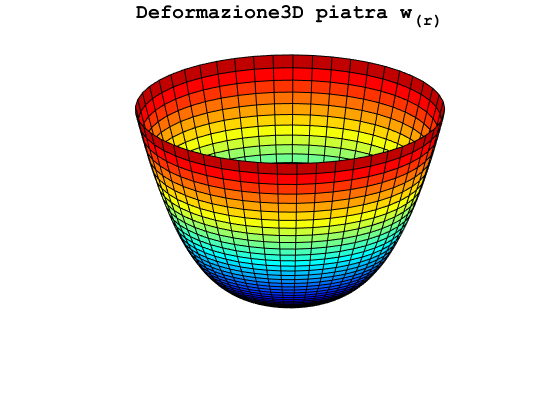


figure(6)
colormap(jet(100))
a3 = linspace(0, 2*pi, 50);    % Angle
rn = linspace(0, R, 50);       % Radius
c=30;
[A,R2]=meshgrid(a3, rn);       % Creat Mesh Matrices
fr=double(wk2(R2));           % Evaluate Function Of ‘R2’ Matrix
[xm,ym,zm]=pol2cart(A,R2,fr);  % Convert To Cartesian
surface(xm, ym, zm)
title(['\fontname{Courier}\fontsize{15}Deformazione3D piatra w_(_r_)'],'color','K');
axis off
view(3)

## Calcolo CDS piastra

a2=0:R/(100-1):R;
%% Plot the mr(r) stresses
figure(7)
mr_n(r)=simplify(D*(-wk2_rr(r)-nu*wk2_r(r)/r))

$$mr\_n(r) = 1.4016\,10^{-6}\,r^{3}-0.0023728\,r^{2}+0.40652\,r-98.616$$

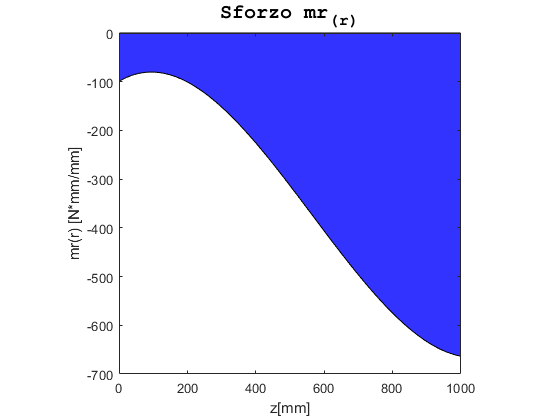

area(a2,double(mr_n(a2)),'FaceColor','b','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo mr_(_r_)'],'color','K');
xlabel('z[mm]');
ylabel('mr(r) [N*mm/mm]');
axis square



m_theta(r)=vpa(D*(-wk2_r(r)/r-nu*wk2_rr(r)))

$$m\_theta(r) = 0.10605\,r-\frac{1.5385\,10^{8}\,\left(-2.1187\,10^{-15}\,r^{4}+4.6737\,10^{-12}\,r^{3}-1.1489\,10^{-9}\,r^{2}+4.9308\,10^{-7}\,r\right)}{r}-0.00064713\,r^{2}+3.9115\,10^{-7}\,r^{3}-22.758$$

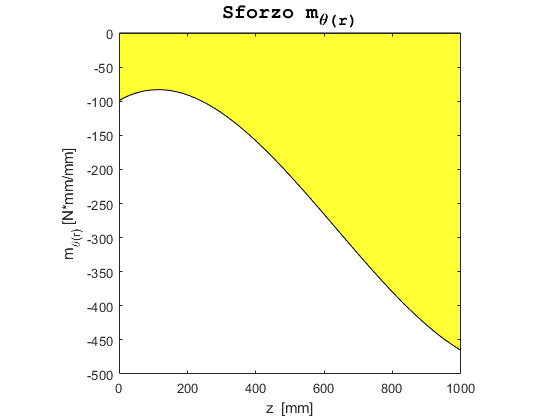

%% Plot the mtheta(r) stresses
figure(8)
mn_theta(r)=simplify(vpa(D*(-wk2_r(r)/r-nu*wk2_rr(r))));
area(a2,double(mn_theta(a2)),'FaceColor','y','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo m_\theta_(_r_)'],'color','K');
xlabel('z  [mm]');
ylabel('m_\theta_(_r_) [N*mm/mm]');
axis square

a3=0.01:R/(100-1):R;
tr(r)=simplify((diff(mr_n*r)-mn_theta)/r)

$$tr(r) = 4.8894\,10^{-6}\,r^{2}-0.0057522\,r+0.53025$$

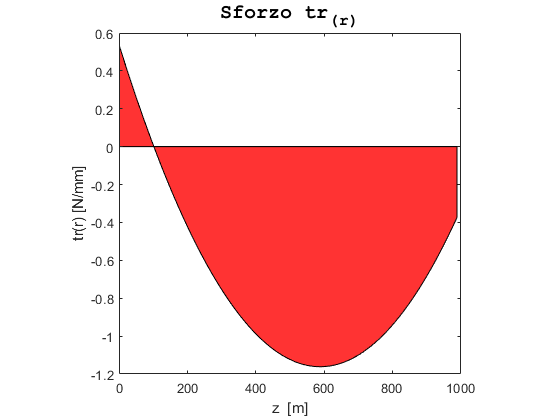

%% Plot the ns(z) stresses
figure(9)
area(a3,double(simplify(tr(a3))),'FaceColor','r','Facealpha',0.8)
title(['\fontname{Courier}\fontsize{15}Sforzo tr_(_r_)'],'color','K');
xlabel('z  [m]');
ylabel('tr(r) [N/mm]');
axis square

## ERRORE RELATIVO

% Errore sul momento
errore=abs(((-mo-mr_n(R)))/mo) % moltiplicando per 100 ottengo l'errore in percentuale

$$errore = 0.020408$$

% Errore sul taglio % per simmetria, il taglio in zero dev'essere nullo
errore=abs(((0-tr(R)))/tr(0)) % moltiplicando per 100 ottengo l'errore in percentuale

$$errore = 0.62726$$